## Stability Analysis for a Boeing 747

#### EAS4010.01: Flight Performance Mechanics 

#### Matthew DeCicco & Sydney Wicket

Cited eqns are from the online AIAA book 

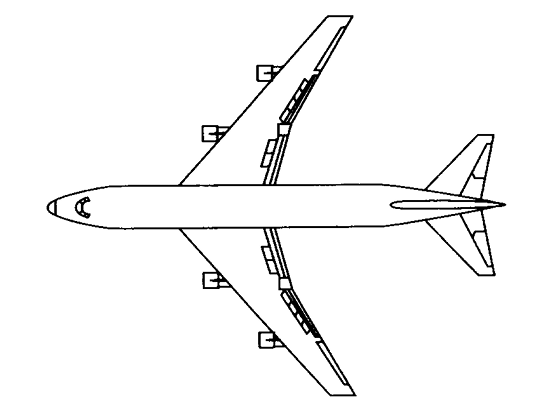

2)

    a) determine the lift and drag forces along with the rolling, pitching and yawing moments generated by your select aircraft at standard, sea-level conditions given the Euler angles and Euler rates.    

    b) determine the acceleration vector, and weight vector in the body axis system and discuss what this means from the pilot’s perspective. Discuss your assumptions, given constants, and key findings as it relates to the aircraft.

**From the book provided in the project outline**

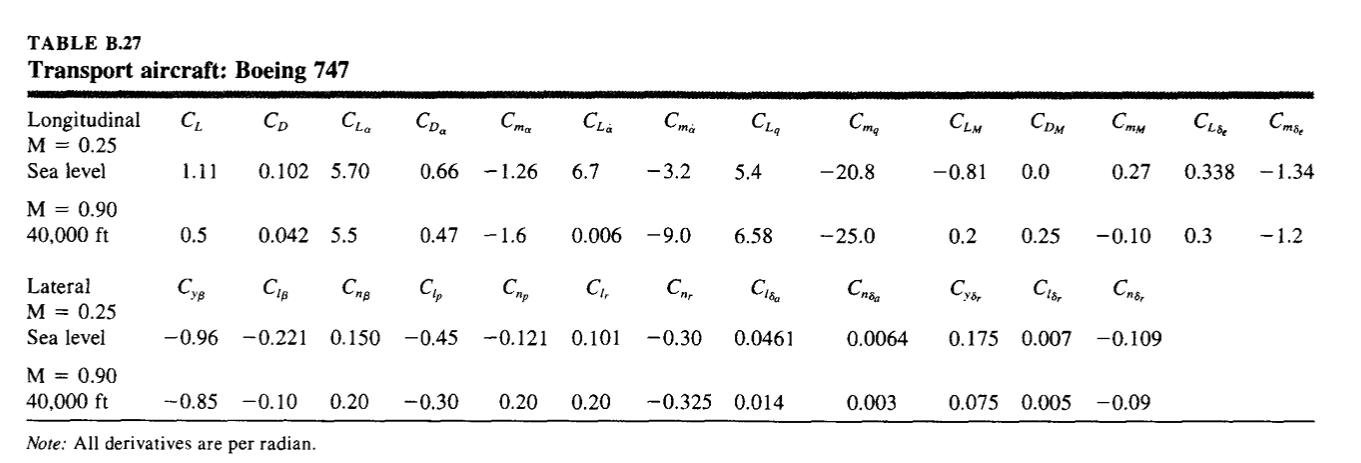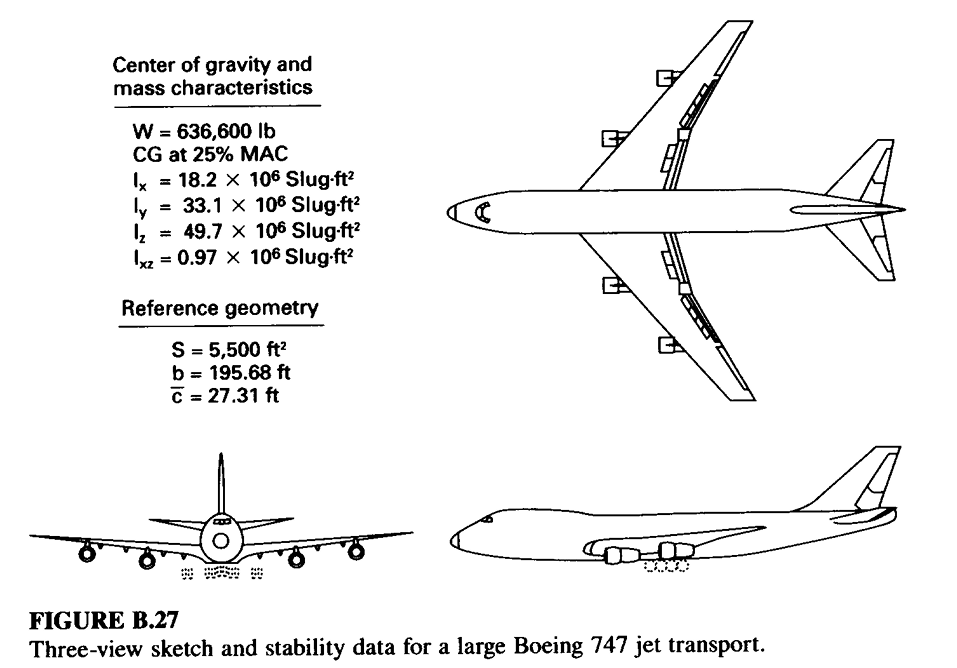

%clc,clear
%Relevant Constants from the book provided in the project outline
Ixx = 18.2e6; %slug-ft^2
Iyy = 33.1e6; %slug-ft^2
Izz = 49.7e6; %slug-ft^2
Ixz = 0.97e6; %slug-ft^2
Weight = 636600; %lb
S = 5500; %Planform Area in ft^2 
M = 0.25; %Mach number for 747 at S.L.
a = 1116.45 ; %ft/s
C_D = 0.102;
C_L = 1.11;
rho_sl = 2.377e-3; %slug/ft^3

V = M*a;
q1 = 1/2 * rho_sl*V^2 ;
Lift = C_L*q1*S;
Drag = C_D*q1*S;
fprintf("The Lift for a Boeing 747 at sea level is %.02f lb\n", Lift);

The Lift for a Boeing 747 at sea level is 565253.72 lb


fprintf("The Drag for a Boeing 747 at sea level is %.02f lb\n", Drag);

The Drag for a Boeing 747 at sea level is 51942.23 lb



%Roll Pitch and Yaw values given by the problem
YawAngle = 90; %Psi in deg
YawAngleDot = 10; %PsiDot in deg/s
PitchAngle = 0; %Theta in deg
PitchAngleDot = 0; %ThetaDot in deg/s
RollAngle = 45; %Phi in deg
RollAngleDot = 5; %PhiDot in deg/s

%{ 
The following moment equations are valid
under the assumptions:
- Mass of Aircraft is Constant
- Aircraft is a Rigid Frame
- Earth Axis System is Inertial Reference Frame
- Aircraft has an xz axis of symmetry
%}

%Using eqn 4.80 page 168 to find roll pitch and yaw rates
Pdeg = (-sind(PitchAngle)*YawAngleDot+RollAngleDot); %Roll Rate in deg
P= deg2rad(Pdeg);
Pdot = 0;
Qdeg = (sind(RollAngle)*cosd(PitchAngle)*YawAngleDot+cosd(RollAngle)*PitchAngleDot); %Pitch Rate in deg
Q = deg2rad(Qdeg);
Qdot = 0;
Rdeg = (cosd(RollAngle)*cosd(PitchAngle)*YawAngleDot-sind(RollAngle)*PitchAngleDot); %Yaw Rate in deg
R = deg2rad(Rdeg);
Rdot = 0;

%Using eqn 4.68 page 161 to find rolling, pitching, and yawing moments
L = Pdot*Ixx + Q*R*(Izz-Iyy)-(Rdot+P*Q)*Ixz; %Rolling Moment
M = Qdot*Iyy-P*R*(Izz-Ixx)-(P^2-R^2)*Ixz; %Pitching Moment
N = Rdot*Izz+P*Q*(Iyy-Ixx)-(Q*R-Pdot)*Ixz; %Yawing Moment
fprintf("The Rolling Moment is %.02f lb-ft\n", L);

The Rolling Moment is 242385.70 lb-ft


fprintf("The Pitching Moment is %.02f lb-ft\n", M);

The Pitching Moment is -331863.37 lb-ft


fprintf("The Yawing Moment is %.02f lb-ft\n", N);

The Yawing Moment is 145696.85 lb-ft


% b) 
v_body = [V 0 0]; 
w_body = [P Q R];

adot_body = [0 0 0]; 

%Eqn 4.33
abar_inertial_body = [ adot_body + cross(w_body,v_body) ]'; 
Acceleration_Magnitude = norm(abar_inertial_body);
fprintf("The intertial acceleration vector in the body axis system is %.02fi + %.02fj+ %.02fk ft/s^2\nThe Pilot will feel %.02f ft/s^2 in total\n", abar_inertial_body,Acceleration_Magnitude);

The intertial acceleration vector in the body axis system is 0.00i + 34.45j+ -34.45k ft/s^2
The Pilot will feel 48.71 ft/s^2 in total


%Eqn 4.21 page 151
FBarGravity_body = [-Weight*sind(PitchAngle);Weight*sind(RollAngle)*cosd(PitchAngle);Weight*cosd(RollAngle)*cosd(PitchAngle)] ; %in lbs
fprintf("The weight vector in the body axis system is %.02fi + %.02fj+ %.02fk lb\n", FBarGravity_body);

The weight vector in the body axis system is -0.00i + 450144.18j+ 450144.18k lb


3) Find the perturbed aerodynamic force along the x stability axis fAx, perturbed aerodynamic force along the y stability axis fAy, perturbed aerodynamic force along the z stability axis fAz, perturbed pitching moment, mA, perturbed rolling moment, lA and perturbed yawing moment, nA, for your selected aircraft if turbulence results in perturbed velocity of 10ft/s, perturbed angle of attack of 1 deg, perturbed sideslip angle of 2 deg, 𝛼̇ = 0.5deg/s, perturbed pitch rate = 1deg/s, perturbed roll rate = 3deg/s, and perturbed yaw rate=3deg/s.

%%Calculations for Part 3
%Perturbations given in the problem statment converted to radians where
%applicable
u = 10; %perturbed velocity [ft/s]
alpha = 1; %perturbed angle of attack [deg]
alpha = deg2rad(alpha);
beta = 2; %perturbed sideslip angle [deg]
beta = deg2rad(beta);
alpha_dot = 0.5; %rate of change of angle of attack [deg/sec]
alpha_dot = deg2rad(alpha_dot);
q = 1; %perturbed pitch rate [deg/sec]
q = deg2rad(q);
p = 3; %perturbed roll rate [deg/sec]
p = deg2rad(p);
r = 3; %perturbed yaw rate [deg/sec]
r = deg2rad(r);

%Constants and solving for longitudinal values using eqn 6.53
U1 = V; %ft
b = 159.68; %ft
c_bar = 27.31;


C_L_1 = (-C_L-C_D*alpha); %From eqn 6.23 and eqn 6.26
C_L_u = -0.81; 
C_L_alpha = 5.7;
C_L_alpha_dot = 6.7;
C_L_q = 5.4;

C_D_1 = -(-C_D + C_L*alpha); %From eqn 6.15 and eqn 6.19
C_D_u = 0;
C_D_alpha = 0.66;
C_D_alpha_dot = 0; %Assumed 0 since most cases downwash lag has little to no effect on drag (Page 255, emailed book)
C_D_q = 0; %Asssumed 0 since drag does not change much with pitch rate. (Page 259, emailed book 6.3.2.4)

C_M_1 = M/(q1*S*c_bar); %Using the pitching moment to find the coeff.
C_M_u = 0.27;
C_M_alpha= -1.26;
C_M_alpha_dot = -3.2;
C_M_q = -20.8;

%
Cofficient_matrix = [-(C_D_u+2*C_D_1) (-C_D_alpha+C_L_1) -C_D_alpha_dot -C_D_q;
                    (C_M_u+2*C_M_1) C_M_alpha C_M_alpha_dot C_M_q;
                    -(C_L_u+2*C_L_1) -(C_L_alpha+C_D_1) -C_L_alpha_dot -C_L_q];

Perturbation_matrix = [ (u/U1);
                        (alpha);
                        ((alpha_dot*c_bar)/(2*U1));
                        ((q*c_bar)/(2*U1))];

Longitudinal_Perturbed_Values = Cofficient_matrix*Perturbation_matrix.*[ q1*S; q1*S*c_bar;q1*S];
fprintf("The perturbed aerodynamic force along the x stability axis, fAx, is %.02f lb\n", Longitudinal_Perturbed_Values(1));

The perturbed aerodynamic force along the x stability axis, fAx, is -18762.39 lb


fprintf("The perturbed pitching moment, mA, is %.02f lb-ft\n", Longitudinal_Perturbed_Values(2));

The perturbed pitching moment, mA, is -461083.58 lb-ft


fprintf("The perturbed aerodynamic force along the z stability axis, fAz, is %.02f lb\n", Longitudinal_Perturbed_Values(3));

The perturbed aerodynamic force along the z stability axis, fAz, is 147.03 lb



%Constants and solving for Lateral values using eqn 6.96, 

C_l_b = -0.221;
C_l_p = -0.45;
C_l_r = 0.101;

C_y_b = -0.96;
C_y_p = 0; %Not given, could be found with eqn 6.70, but we are not provided with enough info.
C_y_r = 0; %Not given

C_n_b = 0.150;
C_n_p = -0.121;
C_n_r = -0.30;


Cofficient_matrix_Lat = [C_l_b C_l_p C_l_r;
                        C_y_b C_y_p C_y_r;
                        C_n_b C_n_p C_n_r];

Perturbation_matrix_Lat = [beta; 
                        ((p*b)/(2*U1)); 
                        ((r*b)/(2*U1))];

Lateral_Perturbed_Values_Lat = Cofficient_matrix_Lat*Perturbation_matrix_Lat.*[q1*S*b;q1*S;q1*S*b];

fprintf("The perturbed rolling moment, lA, is %.02f lb-ft\n", Lateral_Perturbed_Values_Lat(1));

The perturbed rolling moment, lA, is -1052339.57 lb-ft


fprintf("The perturbed aerodynamic force along the y stability axis, fAy, is %.02f lb\n", Lateral_Perturbed_Values_Lat(2));

The perturbed aerodynamic force along the y stability axis, fAy, is -17064.72 lb-ft


fprintf("The perturbed yawing moment, nA, is %.02f lb-ft\n", Lateral_Perturbed_Values_Lat(3));

The perturbed yawing moment, nA, is -86970.32 lb-ft
